# Solving triangular systems

Add the FLAME@lab routines to the path, just in case it was not already in the path.  If this seems to confuse things, just comment it out by putting a "%" at the beginning of the line.

path( '../../flameatlab/util', path )

Use the Spark webpage to implement  unblocked algorithm trsv_lnu_unb_var1( L, y ) that overwrites y with the solution to L x = y, where L is a unit lower triangular matrix.  This variant corresponds to the loop invariant

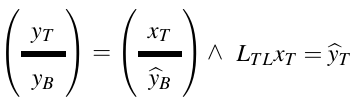

- [Spark webpage](http://edx-org-utaustinx.s3.amazonaws.com/UT1401x/LAFFPfC/Spark/index.html)

n = 5;

Create L:  

L = tril( randi( [-2, 2], [ n, n ] ), -1 ) + eye( n, n );

(notice we create a random matrix, take its strictly lower triangular part, and then add the identity to it to set the diagonal to ones.)

Create a random solution x:

x = randi( [-2,2 ], [ n, 1 ] );

and corresponding right-hand side y:

y = L * x;

Let's see what solving with trsv_lnu_unb_var1( L, y ) yields:

trsv_lnu_unb_var1( L, y )

Compare the result with the initial x:

if isequal( trsv_lnu_unb_var1( L, y ), x )
    disp( 'All is well' );
else
    disp( 'Hmmm, something seems to be wrong' );
end


 % Place output of Spark in this code box.

